# EE105: PWM Speeed Control of a Motor

# Name: Buddy Ugwumba SID: 862063029

## **3. Calculations: **

(2) 

Compute power in and power out.

For power in, using the voltage and the current.

For power out, ($\tau_m \cdot \omega_m$).

At the end, they should be identical.

(3)

Show the bond graph and the state space model in matrix form.

(4)

Compute A, $\zeta$, $\omega_n$, $\omega_d$, $\sigma$.

(5)

Determine the value of the inertia J. Please be careful about the unit of J.

Compute the decay rate.

Compute time constant.

How long will it take the system to reach steady state?

(6)

Compute the DC gain. (Note: The DC gain value is for pulse width of 100%, the vaule decrease with the pulse width.)

(7)

Compute |G(jω)| for f = 100Hz. (Please review the relationship between ω and f.)

Attenuation for different frequencies. Please following the code instruction below.

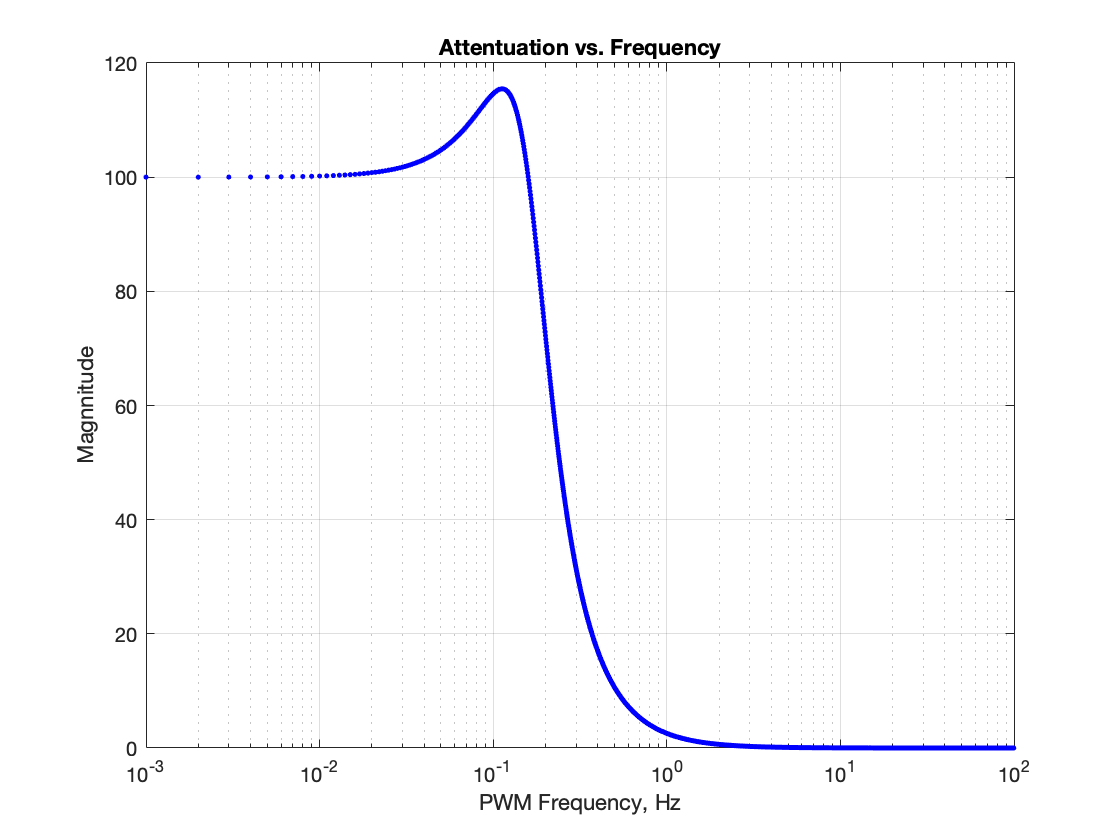

% State-space model description 
R = 0.1;     % ohms
L = 0.1;     % H
K = 0.01;    % unitless
J = 0.001;   % kg.m^2/s^2

A = [-R/L -K/L; K/J 0];
B = [1/L; 0];
C = [0 1];
D = 0;

% Decay  rate 
sig = 0.5;
% Time constant
Tau = 1/sig;
% DC Amplification
DC_amp = K/(J*L);
% Attenuation for different  frequencies
num = K/(J*L); % coefficients of numerator of G(s)
den = [1 R/L (K^(2)/(J*L))]; % coefficients of denominator of G(s)
f = 0:0.001:100;
s = 1i*2*pi*(f);
Gs = abs(polyval(num,s)./polyval(den,s)); 
semilogx(f, Gs, 'b.'); 
grid on; 
xlabel('PWM Frequency, Hz'); 
ylabel('Magnnitude'); 
title('Attentuation vs. Frequency')

(8)

In terms of the graph you get above, does the system effectively keep the DC component and essentially remove all other components? 

(The Attentuation vs. Frequency showing how the DC gain G(s) changes with the frequency. The purpose of low pass filter is to remove the high frequency component, namely, the DC gain will get much smaller when the frequncy increase.)

## **4. Simulation (Lab Assignment): **

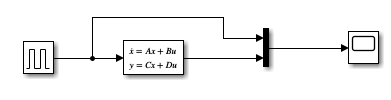

You have defined the matrix A,B,C,D above, just write it to the state-space block.

Set the stop time to 10 time constants.

(1) & (2)

Show the simulation result.

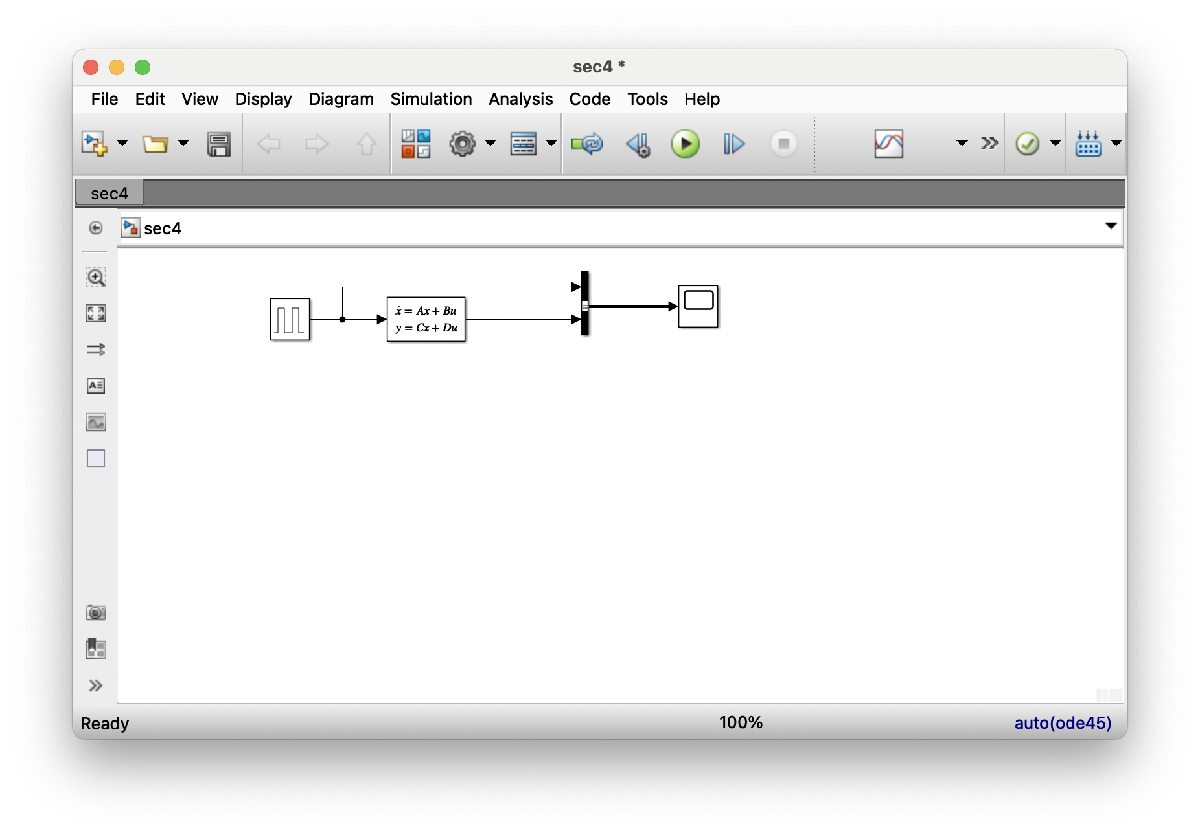

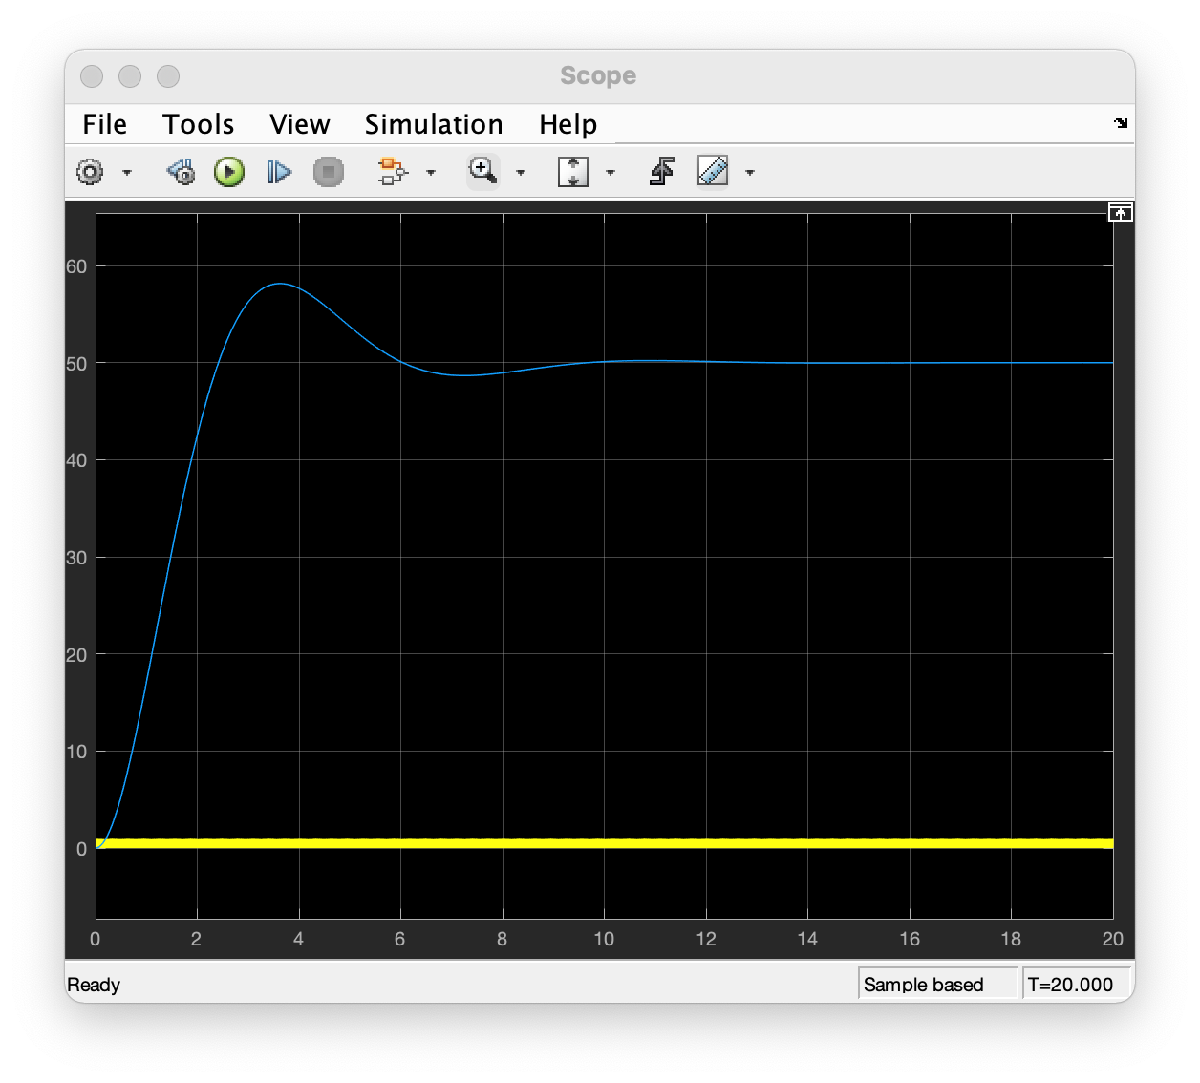

(You will see the steady-state is about 50. Beacause the DC component is $\frac{\tau }{T}B$.)

The steady state is at 50 because that is the percentage of pulse width modulation

(3)  Change the pulse width to 10% and rerun the simulation.

Show the simulation result.

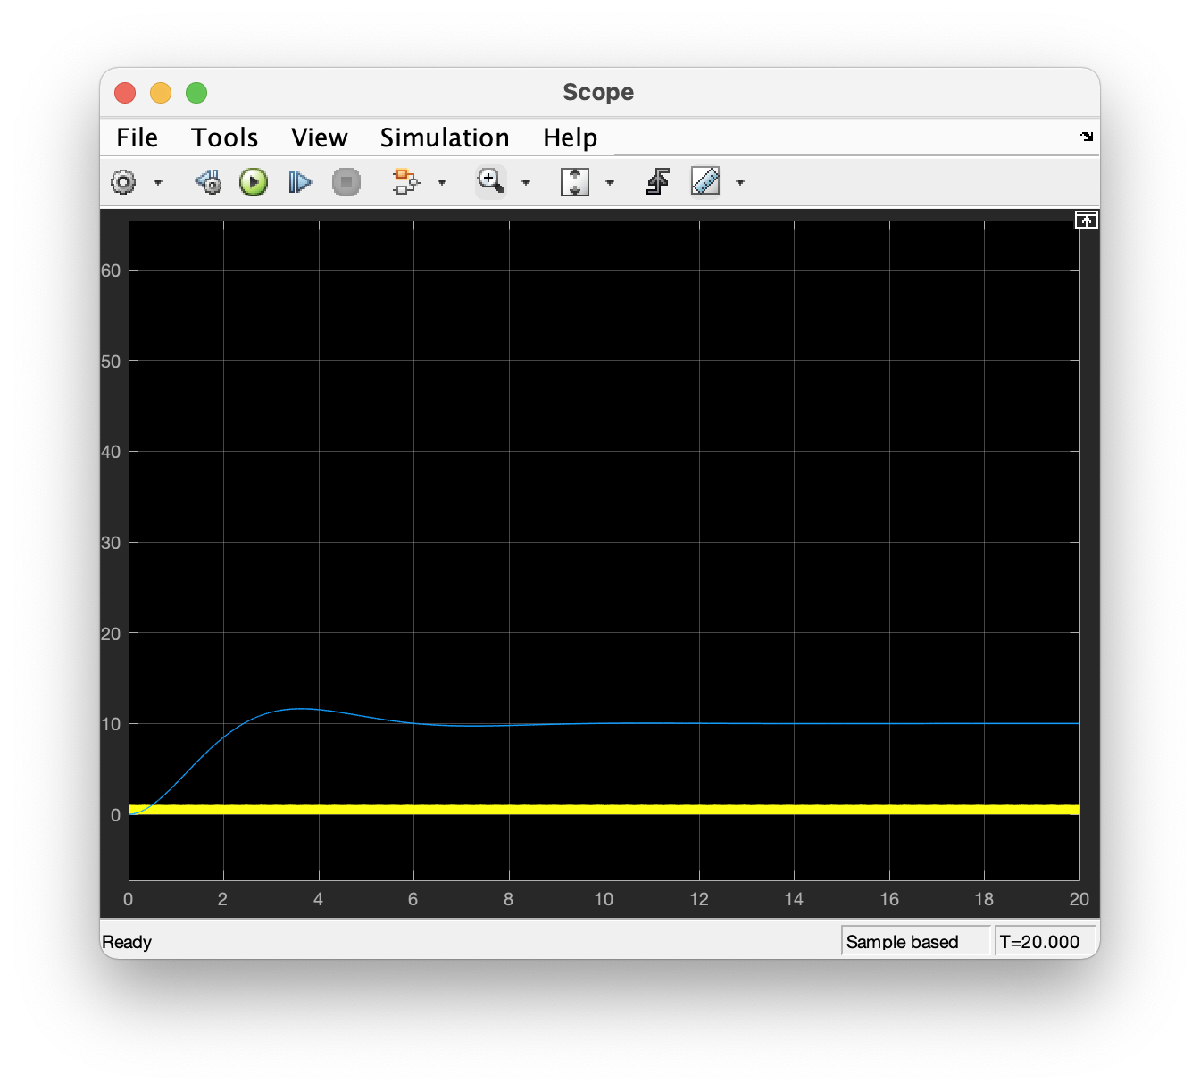

No requirement for the steady-state angular rate plot.

Again the steady state value is at 10 because that is the pulse width modulation.

## 5. Questions:

1.

Answer the question.

The single parameter that determines the DC gain is K because the DC gain is found via 1/K

2.

Answer the question.

If I change the parameter neither the DC gain nor the decay rate will change.

3.

The parameter that would change the decay rate is R. We woiuld need to make it larger in order to decrease time constant without changing the natural frequency

Answer the question.

Show the simulation result.

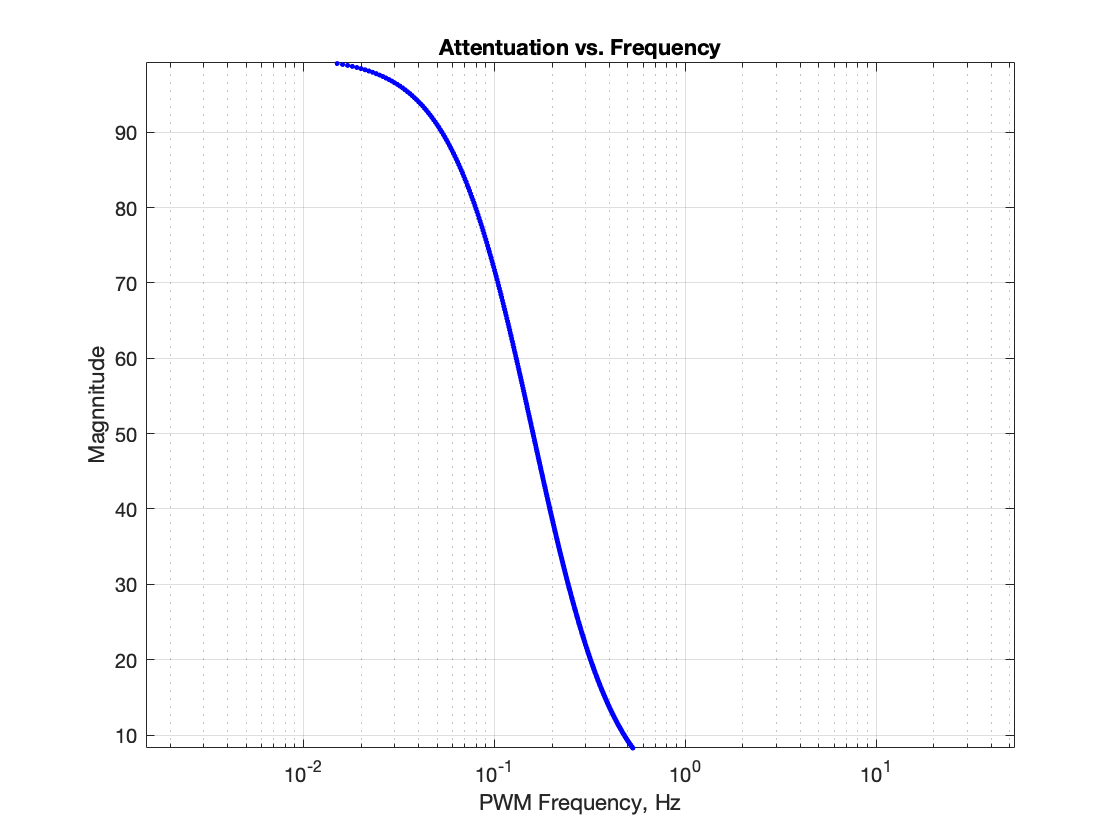

% State-space model description 
R = 0.2;     % ohms
L = 0.1;     % H
K = 0.01;    % unitless
J = 0.001;   % kg.m^2/s^2

A = [-R/L -K/L; K/J 0];
B = [1/L; 0];
C = [0 1];
D = 0;

% Decay  rate 
sig = 0.5;
% Time constant
Tau = 1/sig;
% DC Amplification
DC_amp = K/(J*L);
% Attenuation for different  frequencies
num = K/(J*L); % coefficients of numerator of G(s)
den = [1 R/L (K^(2)/(J*L))]; % coefficients of denominator of G(s)
f = 0:0.001:100;
s = 1i*2*pi*(f);
Gs = abs(polyval(num,s)./polyval(den,s)); 
semilogx(f, Gs, 'b.'); 
grid on; 
xlabel('PWM Frequency, Hz'); 
ylabel('Magnnitude'); 
title('Attentuation vs. Frequency')